# Probabilistic PCA (PPCA) and Bayesian PCA (BPCA)

This script first explores Probabilistic PCA, followed by a discussion of the Bayesian approach to model development.

## Probabilistic PCA

PCA can be reformulated as the maximum likelihood solution of a specific latent variable model, known as probabilistic PCA (PPCA), as proposed in$[1]$. This reformulation serves as an example of the linear-Gaussian framework (all marginal and conditional distributions are Gaussian) and is closely related to the Factor Analysis (FA) model, which is discussed in a subsequent section. PPCA can be formulated by introducing an explicit latent variable $\mathbf{z}$ that represents the principal component subspace$[2]$. Next, a Gaussian prior distribution $p(\mathbf{z})$ over the latent space and a Gaussian conditional distribution $p(\mathbf{x} \mid \mathbf{z})$ for the observed variable $\mathbf{x}$ are defined as shown below:


$$p\left(\mathbf{z}\right) = \mathcal{N} \left(\mathbf{z} \mid \mathbf{0}_K, \mathbf{I}_K \right) \\
 p(\mathbf{x} \mid \mathbf{z}) = \mathcal{N} \left( \mathbf{x} \mid \mathbf{W}\mathbf{z} + \mathbf{\mu}, \sigma^2 \mathbf{I}_D \right)$$


where $K$ is the dimensionality of the principal subspace, $\mathbf{W}$ is a $D \times K$ matrix, $\mathbf{\mu}$ is a $D$-dimensional vector, and $\sigma^2$ is the variance of the conditional distribution, with the precision $\tau = 1/\sigma^2$ also used interchangeably.

Probabilistic PCA can be viewed from a **generative perspective**, where a sample of the observed variable is obtained by first sampling from the latent variable distribution, which is typically a simple distribution (e.g., a multivariate standard normal distribution), followed by applying a linear transformation and adding Gaussian noise. This process is captured by the equation below.


$$\mathbf{x} = \mathbf{W} \mathbf{z} + \mathbf{\epsilon}$$


Model parameters can be determined using maximum likelihood estimation. The first step is to find the marginal distribution $p(\mathbf{x})$, reproduced from $[2]$ below:


$$p(\mathbf{x}) = \int p(\mathbf{x} \mid \mathbf{z}) p(\mathbf{z}) \, \text{d}\mathbf{z} = \mathcal{N} \left( \mathbf{x} \mid \mathbf{\mu}, \mathbf{W}\mathbf{W}^\top + \sigma^2 \mathbf{I} \right)$$


From the above equation, it is evident that the predictive distribution $p(\mathbf{x})$ is governed by the model parameters $\mathbf{\theta} = \{ \mathbf{\mu}, \mathbf{W}, \sigma^2 \}$. However, there exists redundancy corresponding to rotations of the latent space coordinates, such that $\tilde{\mathbf{W}}\tilde{\mathbf{W}}^\top = \mathbf{W}\mathbf{W}^\top$ for all orthogonal matrices $\mathbf{R}$ and $\tilde{\mathbf{W}} = \mathbf{W}\mathbf{R}$. Thus, multiple matrices $\mathbf{W}$ yield the same predictive distribution, highlighting the rotational invariance of the latent space - an issue that also arises in other Factor Analysis (FA) models.

Given the dataset $\mathbf{X} = \{\mathbf{x}_n\}$of observed data points, the PPCA model can be represented as a directed graph, as shown on the left of Figure $[1] $. Maximizing the log-likelihood $\ln p(\mathbf{X} \mid \mathbf{\theta})$ yields the maximum likelihood (ML) solution for the probabilistic PCA model. The solutions for $\(\mathbf{\mu}\)$ and $\(\sigma^2\)$ are omitted here, as they are not relevant for the subsequent analysis. Detailed derivations, including ML solutions for these parameters, can be found in both $[1]$ and $[2]$.


$$\mathbf{W}_{ML} = \mathbf{U}_K \left( \mathbf{L}_K - \sigma^2 \mathbf{I} \right)^{1/2} \mathbf{R}
$$
                    
$$[1]$$


where $ \(\mathbf{U}_K\)$ is an $\(N \times K\)$ matrix whose columns are the $\(K\)$ eigenvectors of the data covariance matrix corresponding to the $\(K\)$ largest eigenvalues, $\(\mathbf{L}_K\)$ is a $\(K \times K\)$ diagonal matrix of those eigenvalues, and, as previously stated, $\(\mathbf{R}\)$ is an arbitrary orthogonal matrix. The orthogonal matrix $\(\mathbf{R}\)$ reflects the non-identifiability of $\(\mathbf{W}\)$ due to the rotational invariance of the latent space. The solution is used to initialize the Bayesian PCA (BPCA) model in one of the experiments.

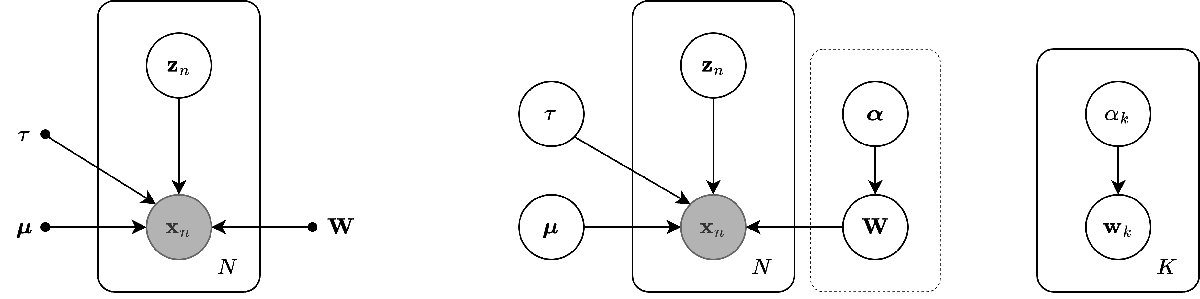

**Figure 1:** The diagram on the left shows the probabilistic PCA model, where $\(\bullet\)$ is used to denote specific instances of model parameters (which are not considered random variables). The box represents the plate notation, containing a dataset of $\(N\)$ observations, $\(\mathbf{x}_n\)$ (indicated by shading), along with the corresponding latent variables, $\(\mathbf{z}_n\)$. The diagram in the middle shows the probabilistic graphical model for Bayesian PCA, illustrating the hierarchical prior over $\(\mathbf{W}\)$, governed by the hyperparameter $\(\mathbf{\alpha}\)$. The diagram on the right illustrates the prior for $\(\mathbf{W}\)$, where $\(\mathbf{w}_k\)$ refers to the$ \(k\)$-th column of $\(\mathbf{W}\)$. The shaded nodes represent observed variables.

Equation $[1]$ shows that the probabilistic PCA model assumes that the dimensionality of the principal subspace is given. In practice, $\(K\)$ is chosen based on the application. For instance, for visualization purposes, $\(K = 2\)$ is often selected. Other approaches involve selecting the dimensionality based on the eigenvalue spectrum of the dataset, where a significant gap between large and small eigenvalues indicates two distinct groups. Alternatively, cross-validation can be employed to select the model with the highest log-likelihood on a validation set. However, these approaches have limitations, as they can be computationally expensive or ineffective for certain datasets (e.g., when no clear gap in the spectrum is present)$[2]$. Consequently, a natural progression is to adopt a Bayesian approach to model selection, where the model parameters $\(\{\mathbf{W}, \mathbf{\alpha}, \mathbf{\mu}, \tau\}\)$ are marginalized with respect to appropriate prior distributions -- this approach is analyzed in the following section. Model is implemented in $\texttt{PPCA}$function below.

## Bayesian PCA

The Bayesian formulation of the PPCA model addresses a key issue in PCA applications: selecting the appropriate number of principal components, or the effective dimensionality of the latent space $[3]$. This is accomplished by introducing a hierarchical prior $\(p(\mathbf{W} \mid \mathbf{\alpha})\)$ over the matrix $\(\mathbf{W}\)$, where each entry $\(\alpha_k\)$ of the vector $\(\mathbf{\alpha}_{K \times 1}\)$ governs the variance of the corresponding column of $\(\mathbf{W}\)$ according to


$$p\left(\mathbf{W} \mid \mathbf{\alpha}\right) = \prod_{k=1}^{K} p\left( \mathbf{w}_k \mid \alpha_k \right) = \prod_{k=1}^{K} \mathcal{N} \left(\mathbf{w}_k \mid \mathbf{0}_K, \alpha_k^{-1} \mathbf{I}_K \right) 
= \prod_{k=1}^{K} \left(\frac{\alpha_k}{2\pi}\right)^{D/2} \exp\left(-\frac{1}{2} \alpha_k \mathbf{w}_k^T \mathbf{w}_k\right)$$


This form of prior is known as an Automatic Relevance Determination (ARD) prior $[4]$. For each $\(\alpha_k\)$ whose posterior distribution is concentrated at large values, the corresponding $\(\mathbf{w}_k\)$ will tend to be small\footnote{In this case, the distribution of the column is a zero-mean Gaussian with very small variance, effectively implying that the posterior distribution approaches a delta function at the origin.}, indicating that the corresponding direction in the latent space can be pruned from the model, resulting in a sparse solution. With this mechanism, the dimensionality of the latent space can be initialized to its maximum possible value, $\(K = D - 1\)$, as the effective dimensionality is determined by the number of finite $\(\alpha_k\)$ values. The probabilistic graphical model for Bayesian PCA is shown in Figure $[1]$.

To complete the specification of the Bayesian model, it is necessary to define priors over the parameters $\(\mathbf{\mu}\)$, $\(\mathbf{\alpha}\)$, and $\(\tau\)$, as provided below.


$$p\left(\mathbf{\alpha}\right) = \prod_{k=1}^K \mathcal{G}\left(\alpha_k \mid a_{\mathbf{\alpha}}, b_{\mathbf{\alpha}}\right) = \prod_{k = 1}^K \frac{1}{\Gamma(a_{\mathbf{\alpha}})} b_{\mathbf{\alpha}}^{a_{\mathbf{\alpha}}} \alpha_k^{a_{\mathbf{\alpha}} - 1} e^{-b_{\mathbf{\alpha}} \alpha_k} \\
p\left(\mathbf{\mu}\right) = \mathcal{N}\left(\mathbf{\mu} \mid \mathbf{0}_D, \beta^{-1} \mathbf{I}_{D}\right) = \left(\frac{\beta}{2 \pi}\right)^{D/2} \exp\left(-\frac{\beta}{2} \mathbf{\mu}^T \mathbf{\mu}\right)
p\left(\tau\right) = \mathcal{G}\left(\tau \mid a_{\tau}, b_{\tau}\right) = \frac{1}{\Gamma(a_{\tau})} b_{\tau}^{a_{\tau}} \tau^{a_{\tau} - 1} e^{-b_{\tau} \tau}$$


To obtain a broad or noninformative (a noninformative prior is employed when limited prior knowledge is available, with the aim of minimizing its influence on the posterior distribution and allowing the data to have a more dominant role in the inference). priors, the hyperparameters of the Gamma distributions are set to $\(10^{-14}\)$. Specifically, the hyperparameters $\(a_{\mathbf{\alpha}}\)$. The bold subscript $\(\mathbf{\alpha}\)$ indicates that all elements of $\(\mathbf{\alpha}\)$ share the same hyperparameters. $\(b_{\mathbf{\alpha}}\)$,$ \(a_{\tau}\)$, and $\(b_{\tau}\)$ are configured in this manner. $\(\beta\)$ is set to $\(10^{-3}\)$ as in $[3]$.

The observations $\(\{\mathbf{x}_n\}\)$are collected in a matrix $\(\mathbf{X}_{D \times N}\)$, and the latent variables$\(\{\mathbf{z}_n\}\)$are similarly collected in a matrix $\(\mathbf{Z}_{K \times N}\)$. The joint distribution of the observations, latent variables, and model parameters can be derived from the probabilistic graphical model shown in Figure $[1]$ and is given below.


$$p\left(\mathbf{X}, \mathbf{Z}, \mathbf{W}, \mathbf{\alpha}, \mathbf{\mu}, \tau\right) = p\left(\mathbf{X} \mid \mathbf{Z}, \mathbf{W}, \mathbf{\mu}, \tau\right) p(\mathbf{Z})p(\mathbf{W} \mid \mathbf{\alpha})p(\mathbf{\alpha})p(\mathbf{\mu}) p(\tau) \\
p\left(\mathbf{X} \mid \mathbf{Z}, \mathbf{W}, \mathbf{\mu}, \tau\right) = \prod_{n=1}^N p\left(\mathbf{x}_n | \mathbf{z}_n, \mathbf{W}, \mathbf{\mu}, \tau\right) = \prod_{n = 1}^N \mathcal{N}\left(\mathbf{x}_n | \mathbf{W}\mathbf{z}_n + \mathbf{\mu}, \tau^{-1} \mathbf{I}_{D}\right)

= \left(\frac{\tau}{2\pi}\right)^{D/2} \exp\left( -\frac{\tau}{2} \left(\mathbf{x}_n - \mathbf{W} \mathbf{z}_n - \mathbf{\mu}\right)^T \left(\mathbf{x}_n - \mathbf{W} \mathbf{z}_n - \mathbf{\mu} \right)\right) \\
p\left(\mathbf{Z}\right) = \prod_{n=1}^N p\left(\mathbf{z}_n\right) = \prod_{n=1}^N \mathcal{N} \left(\mathbf{z}_n \mid \mathbf{0}_K, \mathbf{I}_K  \right)

= \prod_{n=1}^N \frac{1}{(2 \pi)^{K/2}} \exp \left(-\frac{1}{2} \mathbf{z}_n^T \mathbf{z}_n \right)
$$


### Variational distribution

function obj = qMuUpdate(obj)
    covNew = (1/(obj.mu.priorPrec + obj.N * obj.tau.E)) * eye(obj.D);
    muNew = obj.tau.E * covNew * (obj.view.X - obj.W.E * obj.Z.E) * ones(obj.N, 1);
    
    obj.mu.updateParameters(muNew, covNew);
end

## Experiments

## Helper functions

function [W, sigmaSq] = PPCA(X, K)
    [~, D] = size(X);

    if nargin < 2
        K = D - 1; % Maximum value for k
    end

    % Center the data
    X_centered = X - mean(X, 1);
    
    covarianceMatrix = cov(X_centered);
    
    % Eigenvalue decomposition
    [eigVectors, eigValues] = eig(covarianceMatrix);
    
    eigValues = diag(eigValues);
    [sortedEigValues, idx] = sort(eigValues, 'descend');
    
    % ML solution for sigma^2 (Bishop: 12.46)
    sigmaSq = 1./(D - K) * sum(sortedEigValues(K + 1:end));

    % ML solution for W (Bishop: 12.45); R = I;
    W = eigVectors(:, idx(1:K)) * ( diag(sortedEigValues(1:K)) - ...
        sigmaSq * eye(K) )^(1./2);
end

## References

[1] Michael E. Tipping & Christopher M. Bishop, 1999. Probabilistic Principal Component Analysis. Journal of the Royal Statistical Society Series B, Royal Statistical Society, vol. 61(3), pages 611-622. [https://ideas.repec.org/a/bla/jorssb/v61y1999i3p611-622.html](https://ideas.repec.org/a/bla/jorssb/v61y1999i3p611-622.html)

[2] Christopher M. Bishop. 2006. Pattern Recognition and Machine Learning (Information Science and Statistics). Springer-Verlag, Berlin, Heidelberg.

[3] Bishop, C.M. (1999). Variational principal components.

[4] MacKay, D.J. (1995). Probable networks and plausible predictions - a review of practical Bayesian methods for supervised neural networks. Network: Computation In Neural Systems, 6, 469-505.